# MATH 4990/5980 Programming Assignment 5: Boundary Value Problem & the Jacobi Method

**Problem:** Epperson book Exercise Section 2.7 #8 (page 88).

Consider the problem of determining the deflection of a thin beam, supported at both ends, due to a uniform load being placed along the beam.

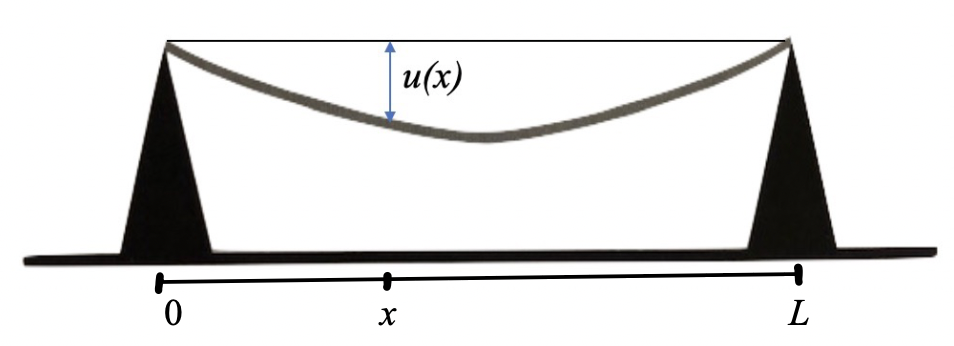

In one simple model, the deflection $u(x)$ as a function of position $x$ along the beam satisfies the following boundary value problem (BVP):


$$-u''+pu=qx(L-x), 0 < x < L$$


$u(0)=u(L)=0$.

Here $p$ is a constant that depends on the material properties of the beam, $L$ is the length of the beam, and $q$ depends on the material properties of the beam, as well as on the size of the load placed on the beam. Suppose the beam is 6-foot long with $p=7 \times 10^{-6}$ and $q=4 \times 10^{-7}$. 

In this project, you will first discretize the given BVP to convert it to a system of linear equations $A \textbf{u} = \textbf{b}$. You will then implement the Jacobi method to approximate the solution to the system, which in turn is the approximate solution $u(x)$ at the points $x_1, x_2,...,x_n$. 

# Instructions/Questions

1.  By using the central difference approximation for the derivative, write the discretization for the second-order ODE given by the above model.

2. Take the mesh size $h=\Delta x = 0.5$ and construct the system of linear equations that results from the discretization in #1. You will get a tridiagonal system $A \textbf{u} = \textbf{b}$.

             The dimension of matrix $A$ is **11x11** 

             The main diagonal entries of $A$ =** 2.00000175**

             The sub-diagonal entries of $A$ = **-1**

             The super-diagonal entries of $A$ = **-1** 

3. Complete the code below that calls the Jacobi subroutine to solve the system of linear equations. The Jacobi subroutine takes as input the matrix $A$, the vector $\textbf{b}$, the initial guess $\textbf{u}^{(0)},$ the error tolerance $TOL$, and the maximum number of iterations $MaxIter$*. *Take $\textbf{u}^{(0)} = (1,1,...,1)^T.$ At each iteration, compute the error $e_i = \| A \textbf{u}^{(i)}-\textbf{b}\|_\infty$ . Set the error tolerance $TOL = 10^{-8}$ and the maximum number of iterations $MaxIter=1000$. Stop the Jacobi iterations when the error $e_i < TOL$ or when the number of iterations hits $MaxIter$*. * 

4. How many iterations does it take for the Jacobi method to reach the desired accuracy?   

    **349 iterations**

The maximum deflection of the beam = **2.0741e-05** attained at $x = $ **3**

Insert the plot of $u(x)$ for $0 \leq x \leq L$ here.

**Solve the system of linear equations using the Jacobi method.**

% This script calls the Jacobi subroutine to approximate the solution 
% of a given linear system.

% Clear all variables and command window
clear
clc
format long %this is needed to show up to 15 decimal digits 


% Define the parameters p, L, q, mesh size h, and dimension nxn for your
% matrix A. Use h=1/2.
h = 1/2;
p = 7e-6; 
L = 6; 
q = 4e-7;
n = 11; 

% Construct the nxn tridiagonal matrix A.
% Use either nested for-loops or built-in command "diag". Use "help diag" 
% for explanation and example. Do not type the entries manually one by 
% one.
A = zeros(n,n);
a = 2+(h^2*q);
c = -1; 
A = diag(a*ones(1,n)) + diag(c*ones(1,n-1),1) + diag(c*ones(1,n-1),-1);
% Construct the vector b using a for-loop. Do not type the entries 
% manually one by one
b = zeros(length(n));
x = 0:0.5:L;

for i=1:n
    b(i) = h^2*q*x(i+1)*(L-x(i+1)); 
end

b = b';

% Construct the initial vector u0=(1,1,...,1). 
u0 = ones(n,1);

% Define the error tolerance and maximum number of iterations
TOL = 10e-8;
MaxIter = 1000;

% Calling Jacobi subroutine to solve the system. This function returns
% u_approx vector containing the appoximation to u(x) at x1, x2,...,xn,
% and a scalar NumIter that gives the number of iterations needed to 
% obtain the approximate solution satisfying the desired accuracy TOL. 

[u_approx, NumIter]=Jacobi(A,b,u0,TOL,MaxIter)

u_approx = 1.0e-04 *

   0.037697949693500
   0.072384918886841
   0.102071897668413
   0.124295864371686
   0.138519847574412
   0.143019838073682
   0.138519847574412
   0.124295864371686
   0.102071897668413
   0.072384918886841


NumIter =    415


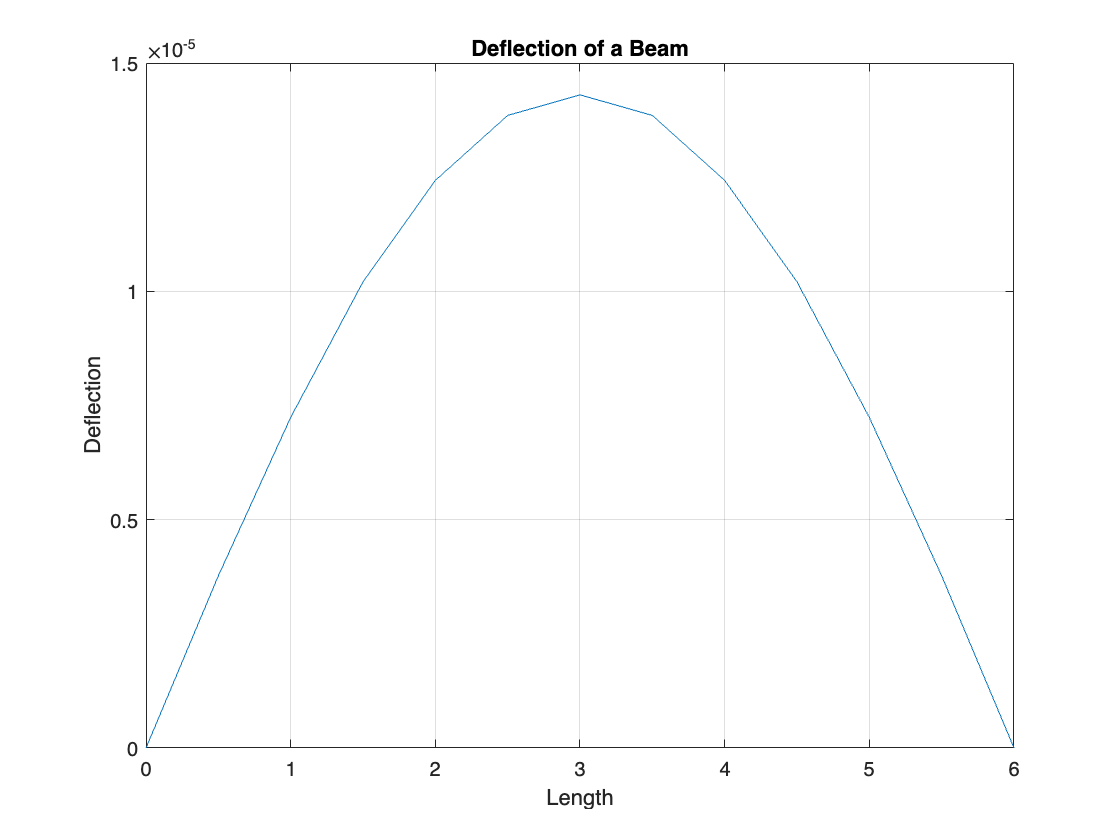

% Plotting the approximate solution curve u(x) for 0<=x<=L. 
% Be sure to label the axes and provide the title of your graph. 
u_plot = zeros(13,1);
u_plot(2:end-1) = u_approx;
plot(x, u_plot)
title('Deflection of a Beam')
xlabel('Length')
ylabel('Deflection')
grid on

% The Jacobi subroutine below takes as inputs the matrix A, 
% vector b, the initial vector u0, error tolerance TOL, maximum number
% of iterations MaxIter, and returns the approximate solution u_approx
% and NumIter the number of iterations needed. 
% 
% At each iteration, we compute the error (error = ||Au-b||) where u is 
% the current approximation. 
% 
% We use the infinity norm to compute the error.
% 
% The algorithm terminates when the error < TOL or when the number of 
% iterations hits MaxIter.

  function [u_approx, NumIter]=Jacobi(A,b,u0,TOL,MaxIter)

      %Construct the splitting matrix M from A and the inverse of M using
      %the built-in command "diag".
      M = diag(diag(A));
      Minv = diag(1./diag(M)); %do not use this but use "diag" command as well
    
      %Construct the matrix N.
      N = M - A;
     
      %Construct the Jacobi iteration matrix Tj and the vector c=(M^-1)b
      Tj = Minv*N;
      c = Minv*b;
     
      %Define the initial approx., initial error, and NumIter
      u_approx = u0;
      error = norm(A*u_approx-b,inf);
      NumIter = 1; % we start with 1 instead of 0 to match the index of u_approx     
     
      while error > TOL && NumIter < MaxIter
          %Perform Jacobi iteration 
          u_new = Tj*u_approx + c;
          
          %Compute the error of the current approximation
          error = norm(A*u_new-b, inf);

          %Overwrite u_approx  
          u_approx = u_new;  

          %Update NumIter
          NumIter = NumIter+1; 
      end

  end